# Plot the 3 4 5 polynomial

## Init

close all

a0 * t^0 + a1 *  t^1 + a2 *  t^2 + a3 *  t^3 + a4 *  t^4 + a5 *  t^5

 0 t^0 + 0 t^1 + 0 t^2 + 10 t^3 -15 t^4 + 6 t^5

P5_position = [0 0 0 10 -15 6];
P5_velocity = [0 0 30 -60 30 0];
P5_acceleration = [0 60 -180 120 0 0];
P5_jerk = [60 -360 360 0 0 0];

|polynomial |t^0   |t^1   |t^2   |t^3   |t^4    |t^5 |  

|---------------|------|------|------|-----|-------|----|

|position          |0	|0	|0	|10	|-15  |6  |

|velocity          |0	|0	|30	|-60	|30  |0  |

|acceleration  |0	|60	|-180 |120 |0     |0  |

|jerk               |60	|-360 |360 |0	|0  |0  |

## Code for 2 seconds with 20 ms / That is the cycle time of Simulator. / Code must be revieved for real axis.

% 20 ms * 100 = 2000 ms
NumberOfPoints = 50;   
% On peut faire ceci car on peut faire un scaling du profil.
% Dans ce cas, on veut un mouvement qui va de 0 à 1
t_xAxis = 0:(1/NumberOfPoints):1;
% With Scaling of 1, motion is 1 [mm]
y_scaling_mm = 25;

## Compute motion profile of *position*

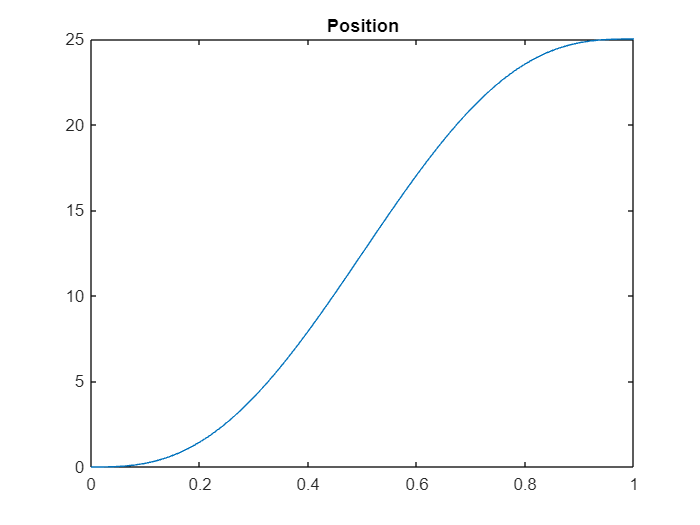

% Define Matrix fo size 1 ; NumberOfPoints + 1
position_yAxis = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    position_yAxis(iLoop) = (t_xAxis(iLoop)^3 * P5_position(4) + t_xAxis(iLoop)^4 * P5_position(5) + t_xAxis(iLoop)^5 * P5_position(6)) * y_scaling_mm;
end
figure
plot(t_xAxis,position_yAxis);
title('Position')

### The same, starting from end position

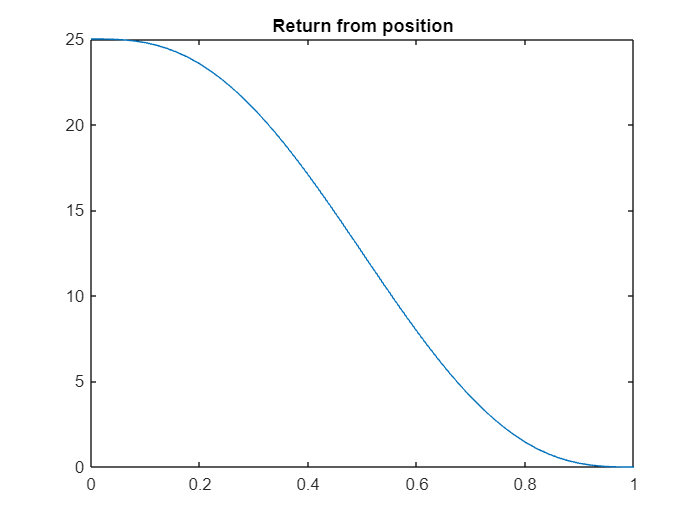

position_yAxisBack = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    position_yAxisBack(iLoop) = y_scaling_mm - (t_xAxis(iLoop)^3 * P5_position(4) + t_xAxis(iLoop)^4 * P5_position(5) + t_xAxis(iLoop)^5 * P5_position(6)) * y_scaling_mm;
end
figure
plot(t_xAxis,position_yAxisBack);
title('Return from position')

## Compute motion profile of *velocity (no unit)*

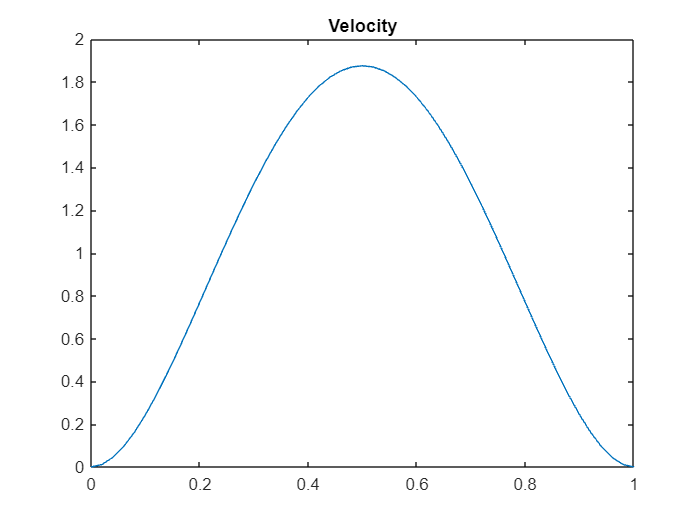

% Define Matrix fo size 1 ; NumberOfPoints + 1
velocity_yAxis = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    velocity_yAxis(iLoop) = t_xAxis(iLoop)^2 * P5_velocity(3) + t_xAxis(iLoop)^3 * P5_velocity(4) + t_xAxis(iLoop)^4 * P5_velocity(5);
end
figure
plot(t_xAxis,velocity_yAxis);
title('Velocity')

## Compute motion profile of *acceleration force / torque  (no unit)*

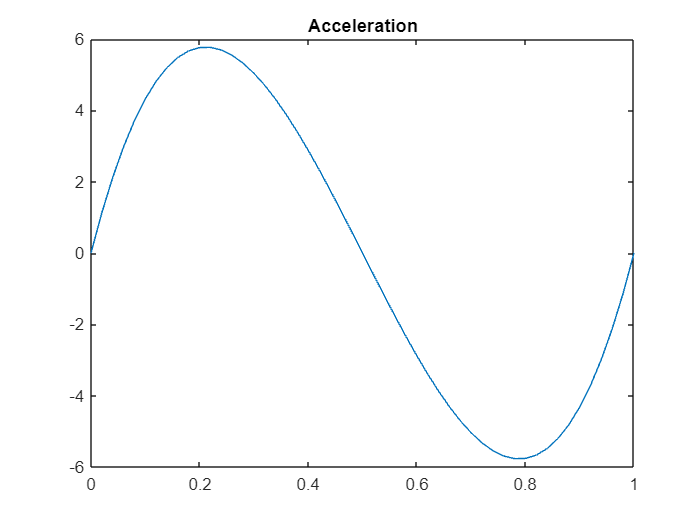

% Define Matrix fo size 1 ; NumberOfPoints + 1
acceleration_yAxis = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    acceleration_yAxis(iLoop) = t_xAxis(iLoop)^1 * P5_acceleration(2) + t_xAxis(iLoop)^2 * P5_acceleration(3) + t_xAxis(iLoop)^3 * P5_acceleration(4);
end
figure
plot(t_xAxis,acceleration_yAxis);
title('Acceleration')

## Compute motion profile of *jerk  (no unit)*

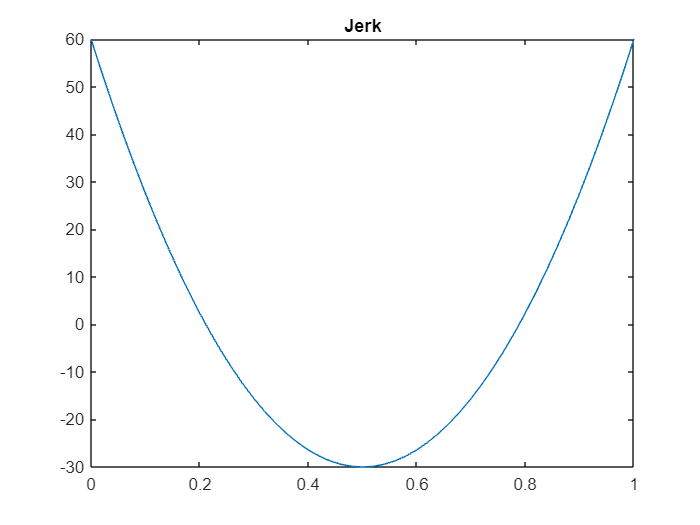

% Define Matrix fo size 1 ; NumberOfPoints + 1
jerk_yAxis = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    jerk_yAxis(iLoop) = t_xAxis(iLoop)^0 * P5_jerk(1) + t_xAxis(iLoop)^1 * P5_jerk(2) + t_xAxis(iLoop)^2 * P5_jerk(3);
end
figure
plot(t_xAxis,jerk_yAxis);
title('Jerk')

End